# PRÁCTICA 3

Ecuación 1 práctica y ecuación 3 apuntes

# Calibración de cámaras en Matlab (Camera Calibrator App)

MatLab dispone de una aplicación para la calibración de cámaras (Camera Calibrator App) que le permite estimar los parámetros intrínsecos y extrínsecos de la cámara, así como los coeficientes de distorsión de la lente empleada. Estos parámetros se pueden emplear en varias aplicaciones de visión por computador como son: eliminar distorsiones en las imágenes, medir objetos sobre un plano y reconstruir escenas tridimensionales mediante el uso de varias cámaras.

## CALIBRACIÓN DE UNA SOLA CÁMARA

Para calibrar la cámara hay que seguir el siguiente diagrama de flujo usando la aplicación.

- Preparar imágenes: Preparar las imágenes y/o la cámara, y el panel de calibración. (damero)

- Añadir imágnes: Cargar/Capturar las imágenes

- Calibración: Calibrar la cámara

- Evaluación: Evaluar la precisión de la calibración

- Mejora: Ajustar los parámetros para mejorar la precisión (si fuese necesario)

- Exportar resultados: Exportar el resultado de la calibración

### cameraCalibrator

En esta práctica se va a emplear esta herramienta para calibrar dos cámaras, una Intel RealSense 435 RGB y una GoPro que monta un gran angular que deforma la imagen de manera considerable. Para ello se utilizarán imágenes contenidas en los subdirectorios ‘RealSense’ y ‘GoPro’ las que muestran un panel de calibración tipo damero con casillas de 30x30 mm y 50x50 mm respectivamente.

## CARGAR IMÁGENES

#### EJERCICIO 1

Cargue las imágenes ‘realsense01.png’ a ‘realsense20.png’ (20 imágenes en total). Dichas imágenes están contenidas en el subdirectorio ..\Practica03\RealSense. Especifique un tamaño de celda de 30x30.

cameraCalibrator

#### EJERCICIO 2

Visualice las imágenes descartadas por el sistema de calibración

- realsese20.pic: rechazada porque tiene una libreta sobre el tablero

#### EJERCICIO 3

Compruebe visualmente que se han detectado correctamente los puntos de cruce del panel en las imágenes de calibración aceptadas

- El origen se dibuja en color naranja

## CALIBRAR

El algoritmo de calibración emplea inicialmente un modelo pin hole sin distorsión, estimando una matriz de parámetros intrínsecos únicos para la cámara y una matriz de rotación y vector de translación para cada una de las imágenes. Posteriormente calcula los coeficientes de distorsión mediante minimización no lineal de mínimos cuadrados:

#### EJERCICIO 4

Realice la calibración con las imágenes suministradas con el objetivo de obtener una matriz de parámetros intrínsecos, 2 coeficientes de distorsión radial y una matriz de rotación y un vector de traslación para cada imagen (posiciones de la cámara).

## EVALUAR EL RESULTADO DE LA CALIBRACIÓN.

- Sobre cada imagen se representan tanto los puntos detectados como los proyectados empleando con el modelo del cámara obtenido durante la calibración (1)

- Muestra el error medio en píxeles para cada imagen (2)

- Representa los parámetros extrínsecos en el espacio 3D (3)

- Permite corregir la distorsión de la imagen (4)

#### EJERCICIO 5

Analice los resultados obtenidos. ¿En qué posición se producen mayores errores?

- Cuando el tablero no es perpendicular a la cámara

## EXPORTAR EL RESULTADO DE LA CALIBRACIÓN

Una vez completada la calibración es posible exportar los parámetros como un objeto del tipo cameraParameters o bien mediante un MATLAB script. Este script permite repetir la calibración completa y mostrar el resultado de la misma.

#### EJERCICIO 6

Exporte el resultado de la calibración sobre una variable llamada parametrosRealSense.

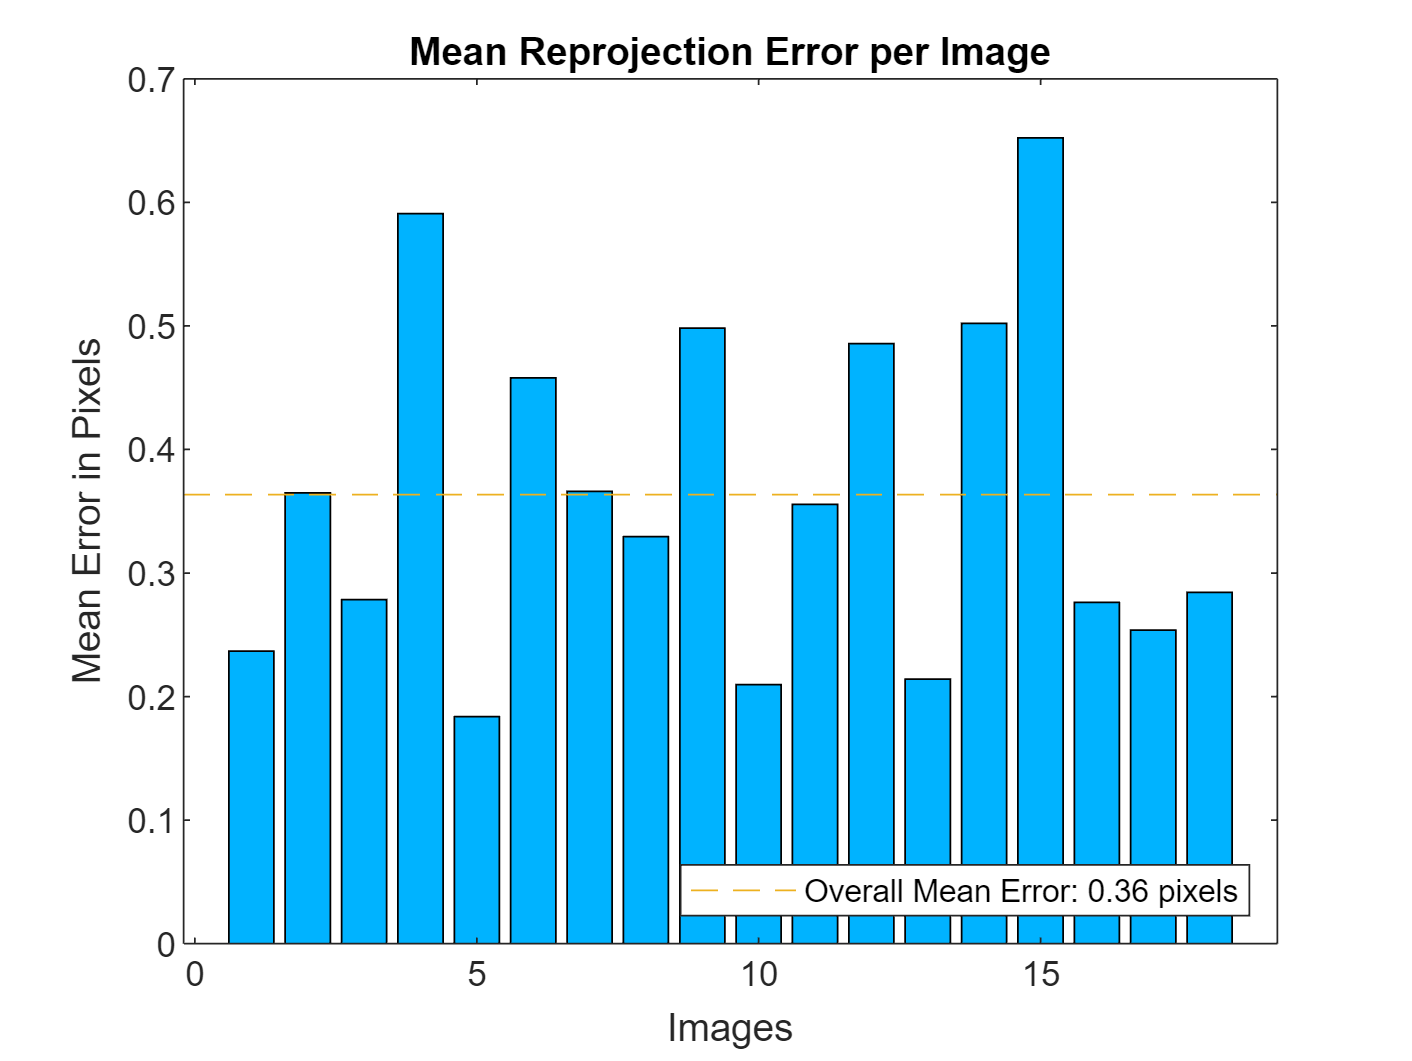

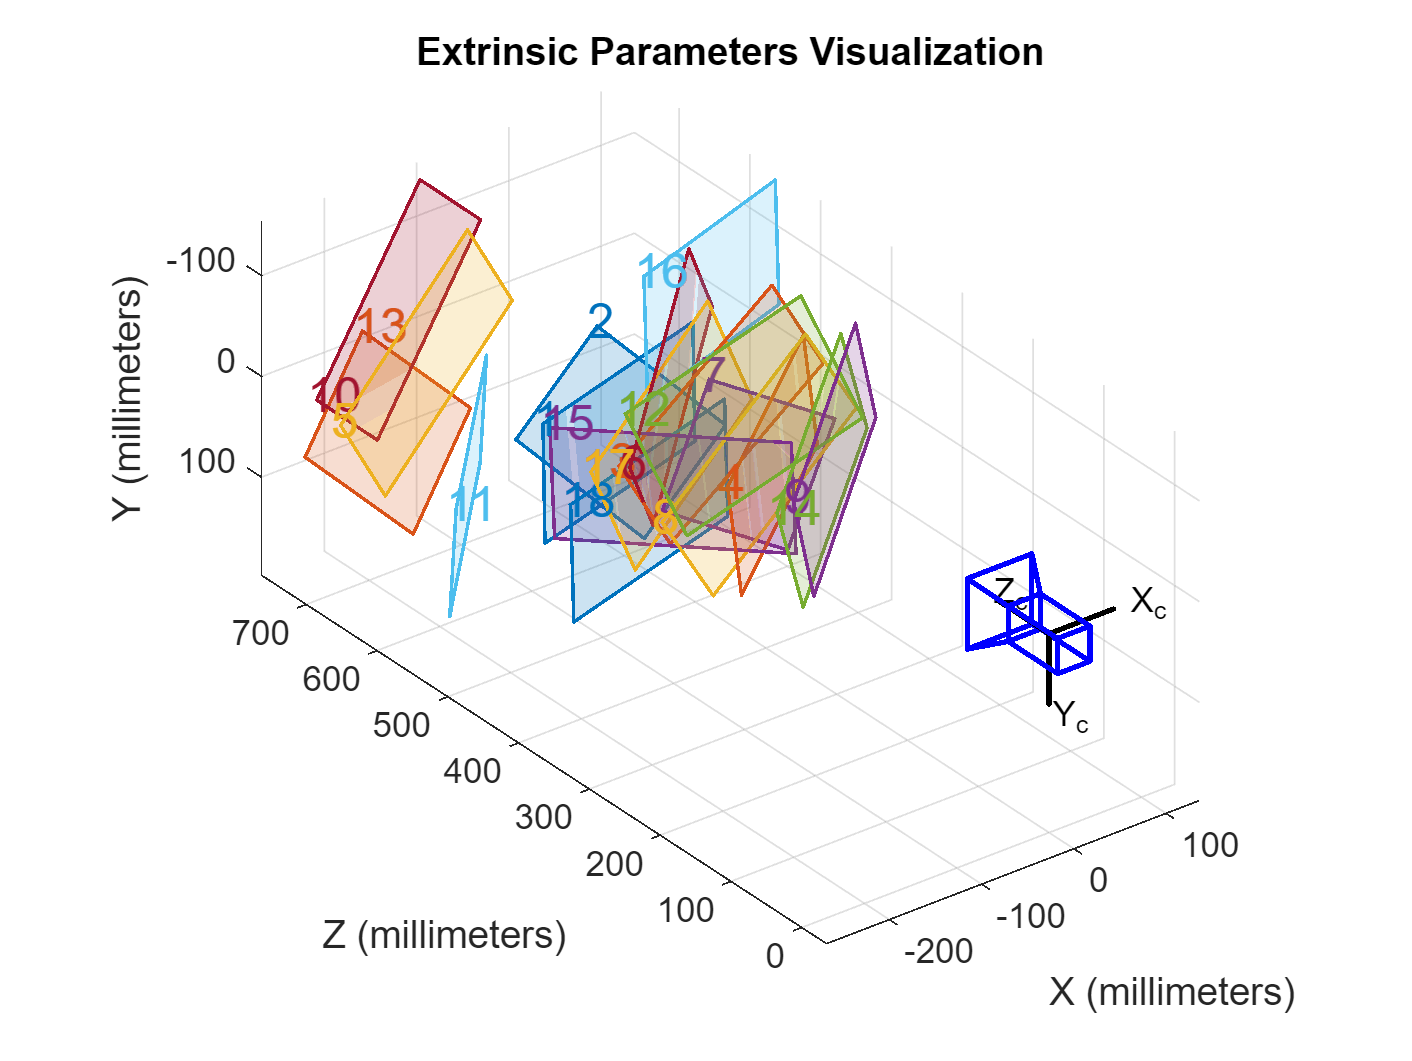


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  601.6073 +/- 2.1617      599.1006 +/- 2.1584  ]
Principal point (pixels):[  323.6827 +/- 1.4180      240.4458 +/- 0.7374  ]
Radial distortion:       [    0.0617 +/- 0.0074       -0.1041 +/- 0.0288  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0057 +/- 0.0059       -0.2554 +/- 0.0045       -0.0256 +/- 0.0008  ]
                         [    0.0240 +/- 0.0054       -0.0265 +/- 0.0045        0.8111 +/- 0.0007  ]
                         [    0.0430 +/- 0.0049       -0.0956 +/- 0.0034       -0.5448 +/- 0.0005  ]
                         [    0.0062 +/- 0.0019       -0.5901 +/- 0.0024       -0.1837 +/- 0.0006  ]
                         [    0.0924 +/- 0.0116       -0.2476 +/- 0.0087       -0.5701 +/- 0.0015  ]
                         [    0.2037 +/- 0.0026       -0.5938 +/- 0.0029       -0.6107 +/- 0.0007  ]
 

scrptParametrosRealSense();

Una variable de tipo cameraParameters contiene un total de 18 campos que reflejan el resultado de la calibración.

parametrosRealSense = cameraParams

parametrosRealSense =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [18×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.3633
                 ReprojectionErrors: [40×2×18 double]
                  ReprojectedPoints: [40×2×18 double]

   Calibration Settings
                        NumPatterns: 18
                  DetectedKeypoints: [40×18 logical]
                        WorldPoints: [40×2 double]
                         WorldUnits: 'millimeters'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


#### EJERCICIO 7

Almacene y muestre la matriz de parámetros intrínsecos en la variable K (es única para la cámara)

%EJERCICIO 7
% K = parametrosRealSense.K'
K = parametrosRealSense.K % no vale para la fórmula porque es la traspuesta de la que necesitamos

K =   601.6073         0  323.6827
         0  599.1006  240.4458
         0         0    1.0000


K = parametrosRealSense.IntrinsicMatrix % esta es la que usamos, cx=323.4 (640/2), cy=240.6 (480/2)

K =   601.6073         0         0
         0  599.1006         0
  323.6827  240.4458    1.0000


¿Se corresponde la coordenada del punto principal con el centro del sensor?

puntoPrincipal = K(3,1:2)

puntoPrincipal =   323.6827  240.4458


imRS1 = imread('RealSense\realsense01.png');
centro = [size(imRS1,2)/2 size(imRS1,1)/2]

centro =    320   240


errorCentro = centro-puntoPrincipal

errorCentro =    -3.6827   -0.4458


- Aproximadamente. Se desvía 3 pixeles en el eje x

#### EJERCICIO 8

Almacene y muestre la matriz de rotación y el vector de translación para la cámara en la posición 3 (variables R y t respectivamente)

- Nota: Los índices en la variable de calibración para cada posición se corresponde con el número que la aplicación le ha asignado a la imagen correspondiente y no al nombre del fichero que contiene la imagen.

%EJERCICIO 8
%R =pRealSense.PatternExtrinsics(3).R'
%t =pRealSense.PatternExtrinsics(3).Translation % .Translations

numImagen = 3;
R3= parametrosRealSense.RotationMatrices(:,:,numImagen)

R3 =     0.8509   -0.5193    0.0794
    0.5152    0.8545    0.0662
   -0.1022   -0.0154    0.9946


t3 = parametrosRealSense.TranslationVectors(numImagen,:)

t3 =  -138.4257  -19.3017  427.2958


#### EJERCICIO 9

Según la ecuación 1, obtenga la matriz una matriz M de 4x3 que modele la cámara ubicada en la posición 3. 

%EJERCICIO 9
% M = [R;t]*K
M3 =  [R3 ; t3] * K % paso de coordenades del mundo real a pixeles de la cámara

M3 = 1.0e+04 *

    0.0538   -0.0292    0.0000
    0.0331    0.0528    0.0000
    0.0260    0.0230    0.0001
    5.5030    9.1178    0.0427


Emplee dicha matriz para calcular donde se proyectan los puntos de 3D de coordenadas (-30, -30, 0), (-30, 150,0), (240,150,0) y (240,-30,0), los cuales representan los puntos extremos de la rejilla expresados en milímetros, los puntos debe guardarlos en una variable llamada ‘puntos’, cada punto en una fila (4x3).

% coordenada aumentadas
p = [-30 -30 0 1; -30 150 0 1; 240 150 0 1;240 -30 0 1]

p =    -30   -30     0     1
   -30   150     0     1
   240   150     0     1
   240   -30     0     1


% puntosH = p*M
puntosH = p*M3

puntosH = 1.0e+05 *

    0.2896    0.8410    0.0042
    0.8861    1.7911    0.0043
    2.3377    1.0027    0.0046
    1.7412    0.0526    0.0044


% hom2cart: homogéneas a cartesianas
puntos = puntosH./puntosH(:,3)

puntos =    68.4746  198.8578    1.0000
  203.7796  411.9021    1.0000
  512.3432  219.7655    1.0000
  391.8370   11.8419    1.0000


hom2cart(puntosH)

ans =    68.4746  198.8578
  203.7796  411.9021
  512.3432  219.7655
  391.8370   11.8419


NOTA: tenga en cuenta que se las coordenadas en el plano imagen se obtienen inicialmente en su forma homogénea.xy1 = wxy1 ./ wxy1(:,3) % [x y 1]

#### EJERCICIO 10

Superponga los puntos obtenidos anteriormente sobre la imagen correspondiente empleando función de Matlab fill (rellena la región determinada por un conjunto de puntos).

figure;
im3 = imread("./Realsense/realsense03.png");
imshow(im3);
hold on
fill (puntos(:,1), puntos(:,2), 'r' ,'FaceAlpha', 0.5);
axis on

puntos2d = ginput(1)

#### EJERCICIO 11

Una vez completada la práctica repita los ejercicios del 7 al 10 con otras imágenes

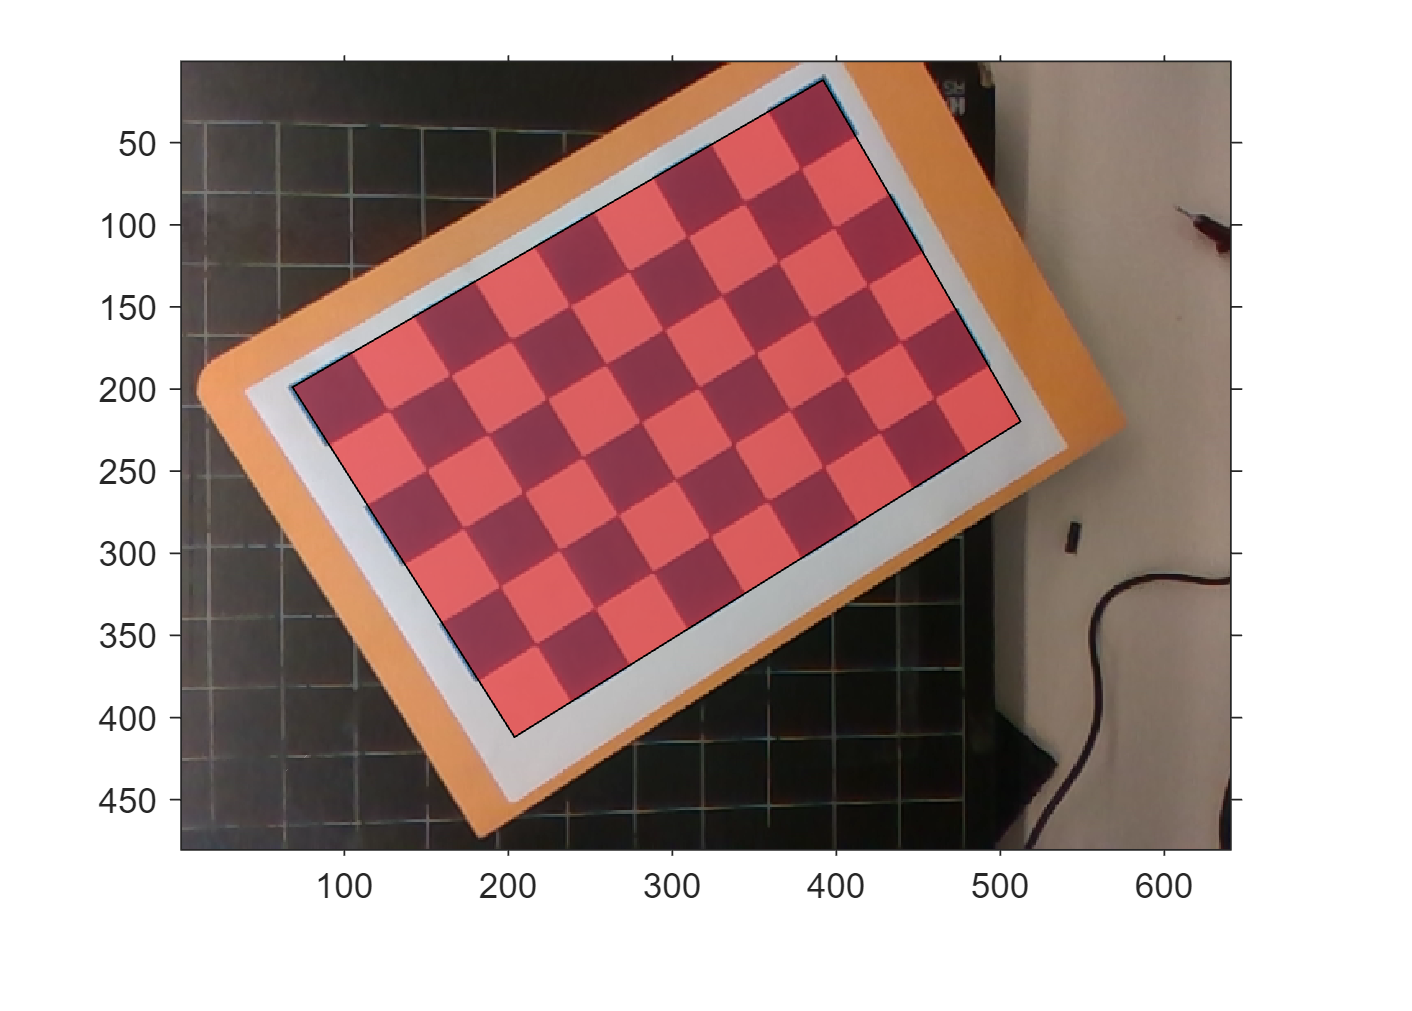

numImagen = 4;
p = [-30 -30 -20 1; -30 150 -20 1; 240 150 -20 1;240 -30 -20 1]
R = parametrosRealSense.RotationMatrices(:,:,numImagen)
t = parametrosRealSense.TranslationVectors(numImagen,:)

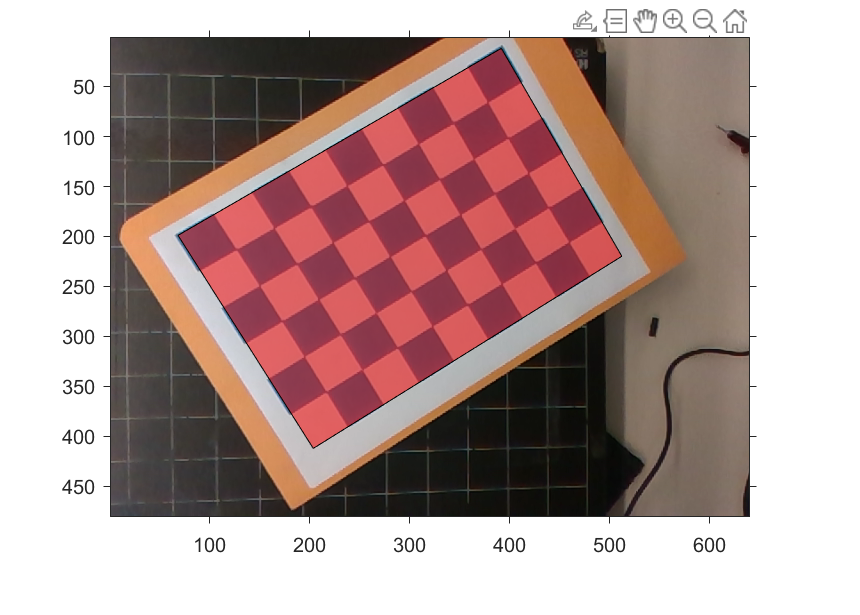

puntos2d =    72.0000  199.0000


M =  [R ; t] * K % paso de coordenades del mundo real a pixeles de la cámara
puntos = hom2cart(p*M)

im = imread(sprintf("./Realsense/realsense%02d.png", numImagen));
imshow(im);
hold on;
fill (puntos(:,1), puntos(:,2), 'r' ,'FaceAlpha', 0.5);
axis on;

p =    -30   -30   -20     1
   -30   150   -20     1
   240   150   -20     1
   240   -30   -20     1


grid on;

R =     0.8150   -0.1740    0.5527
    0.1705    0.9836    0.0584
   -0.5538    0.0467    0.8313


## CORRECCIÓN DE IMÁGENES

Una vez realizada la calibración de la cámara es posible emplear el resultado obtenido para corregir las distorsiones producidas por la lente y posibles errores de montaje.

#### EJERCICIO 12

Realice la calibración de una cámara GoPro con gran angular a partir de las imágenes contenidas en el subdirectorio ‘..\Practica03\GoPro’. 

scriptParametrosGoPro();

t =   -83.4111  -17.0346  345.3931


Exporte el resultado sobre la variable parametrosGoPro y muestre los coeficientes de distorsión radial obtenidos.

parametrosGoPro = cameraParams;

M = 1.0e+04 *

    0.0669    0.0029    0.0001
    0.0121    0.0603    0.0000
   -0.0064    0.0228    0.0001
    6.1617    7.2843    0.0345


parametrosGoPro.RadialDistortion

puntos =   126.2064  158.8975
  190.1869  492.0759
  514.1324  352.3367
  478.3250  124.1288


#### EJERCICIO 13

Emplee el botón ‘show undistorted’ de la propia aplicación de calibración para mostrar cada imagen corregida.

- ´Ver sesión de calibración

#### EJERCICIO 14

Muestre sobre una figura las imágenes ‘gopro01.jpg’ y ‘gopro05.jpg’ con distorsión y el resultado de corregirlas. (subplot(2,2,..))

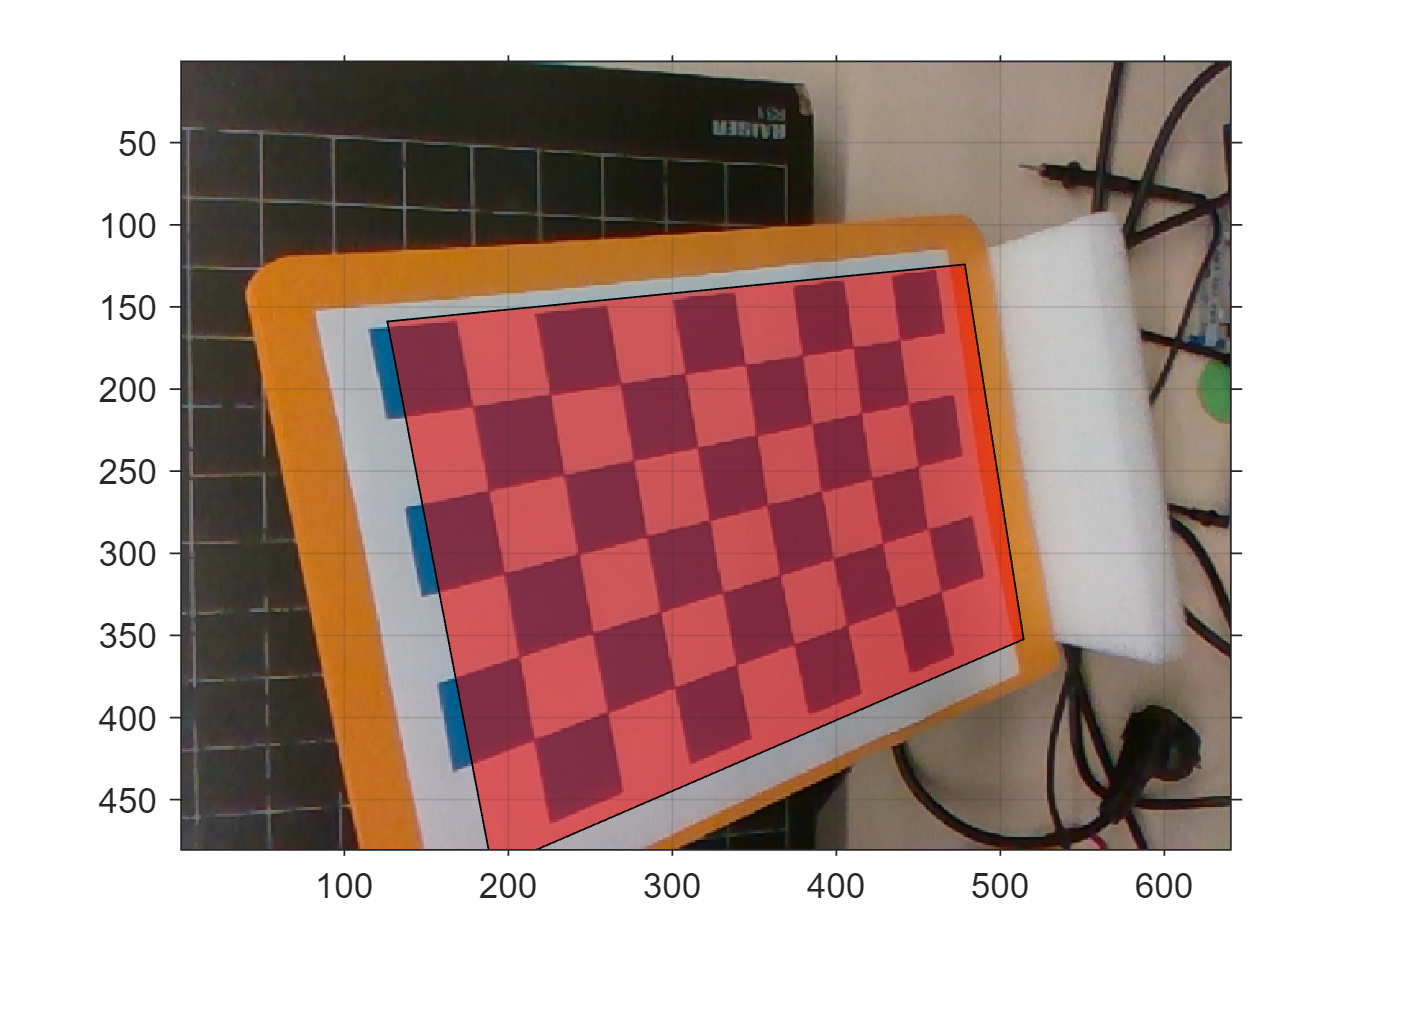

numImagen = 1;
figure;
subplot(2,2,1);
imd = imread(sprintf("./GoPro/gopro%02d.jpg", numImagen));
imshow(imd);


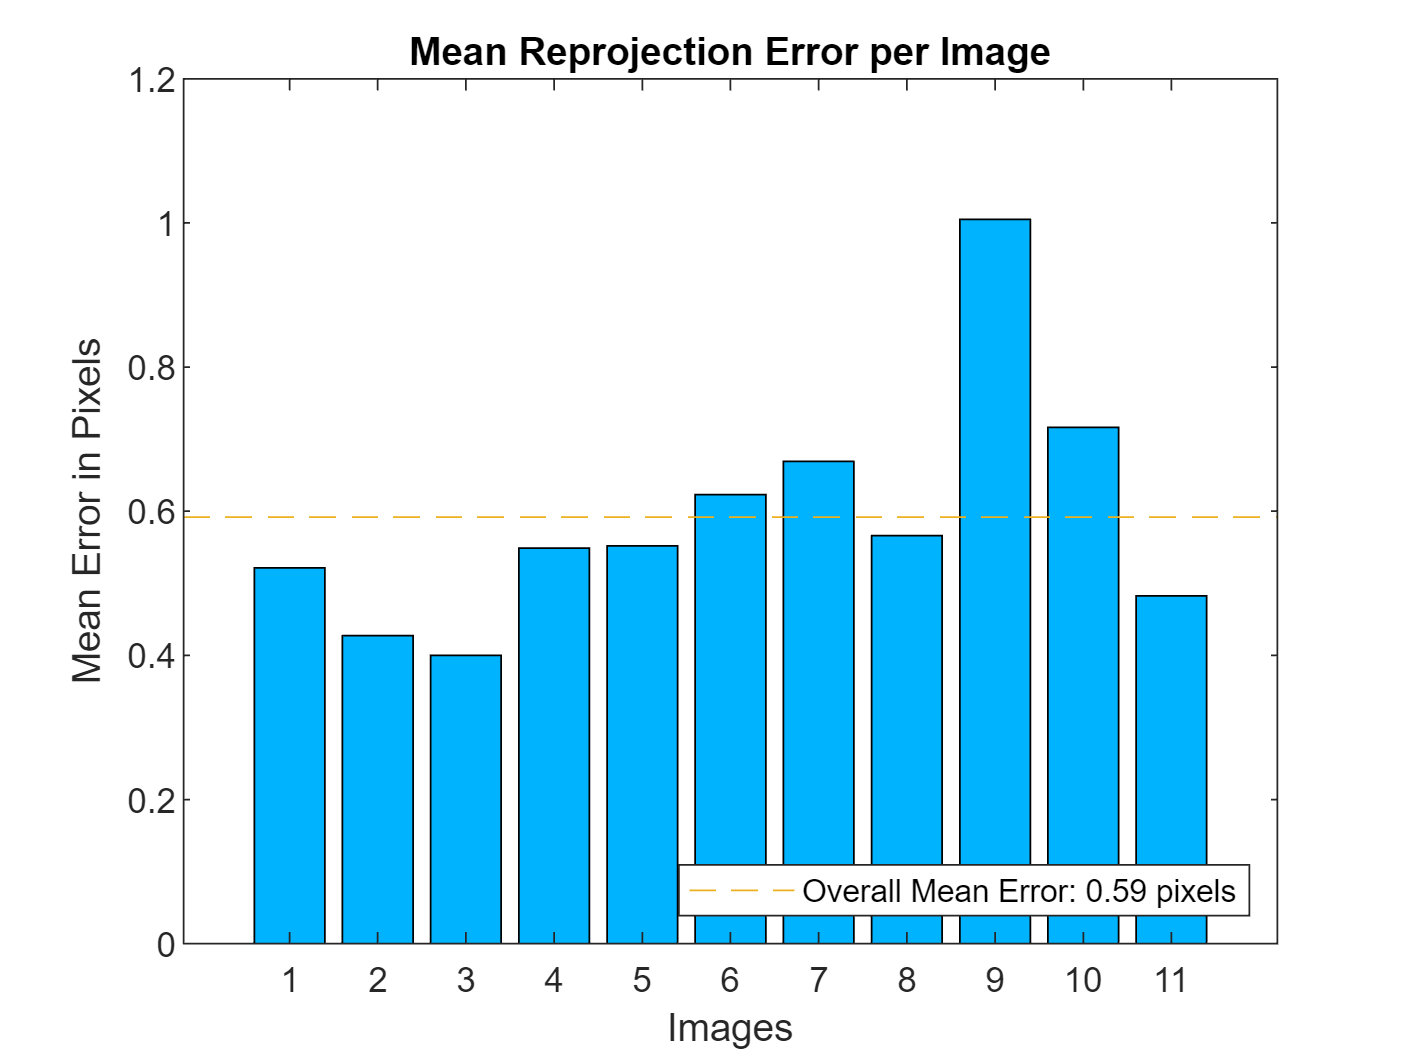

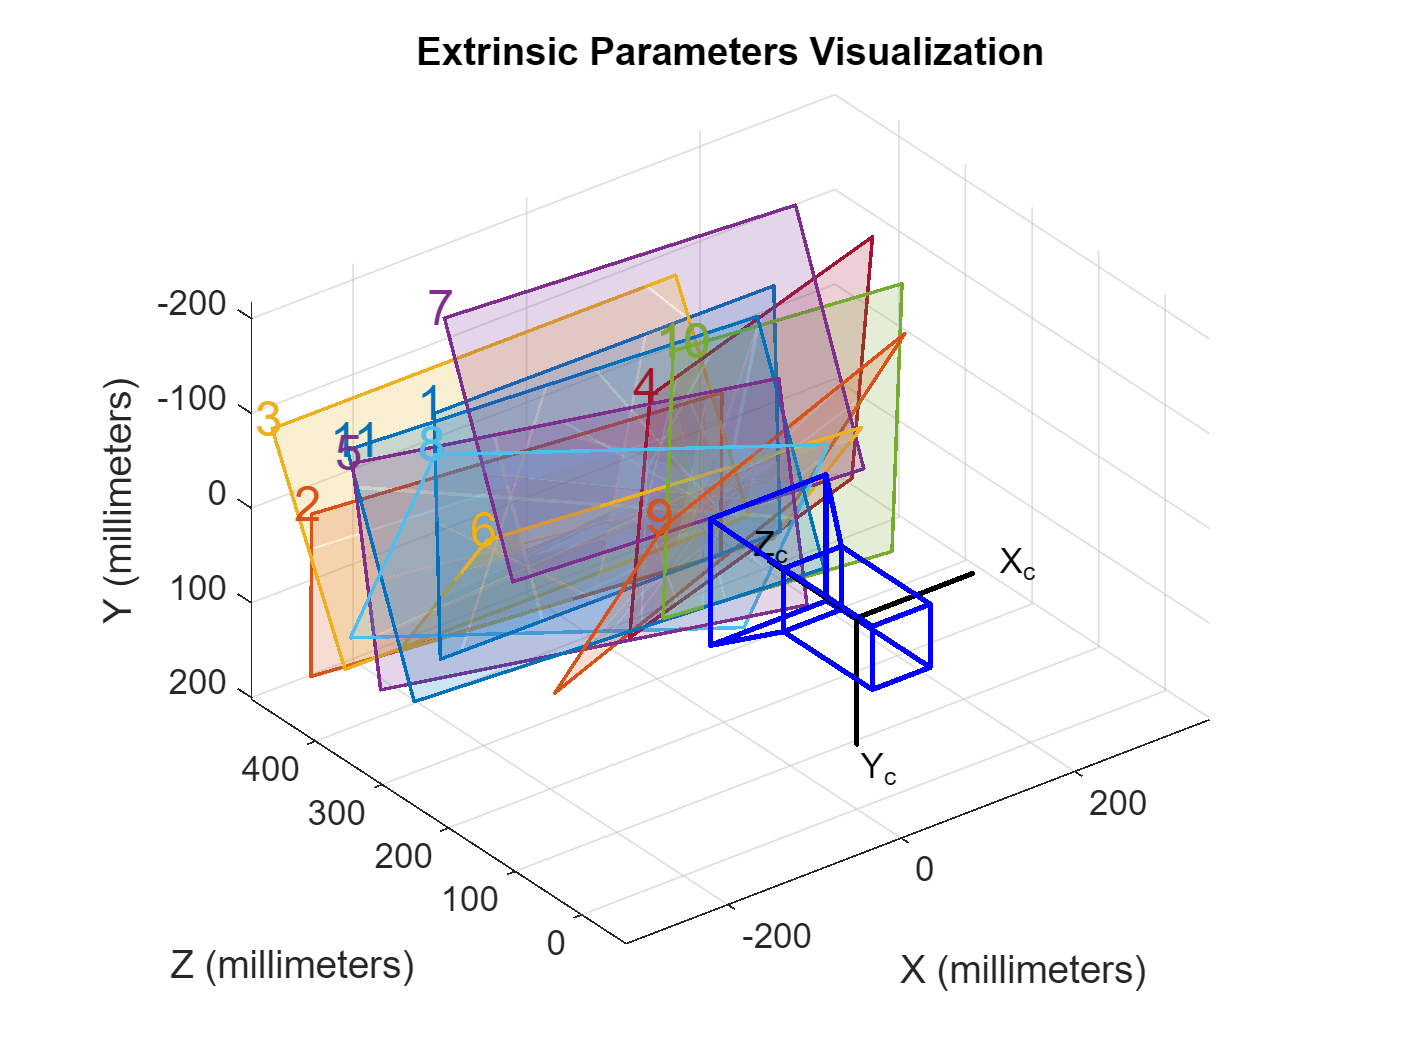


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  873.2617 +/- 0.9329      872.4386 +/- 0.9150  ]
Principal point (pixels):[ 1006.5832 +/- 0.7118      743.3432 +/- 0.5749  ]
Radial distortion:       [   -0.2549 +/- 0.0012        0.0689 +/- 0.0011  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0693 +/- 0.0011       -0.0274 +/- 0.0009        0.0258 +/- 0.0002  ]
                         [    0.3624 +/- 0.0010        0.2953 +/- 0.0010       -0.1965 +/- 0.0003  ]
                         [   -0.2154 +/- 0.0010        0.3446 +/- 0.0010       -0.1941 +/- 0.0003  ]
                         [    0.0283 +/- 0.0009       -0.3797 +/- 0.0010        0.0829 +/- 0.0003  ]
                         [    0.0147 +/- 0.0008        0.4574 +/- 0.0009       -0.1214 +/- 0.0003  ]
                         [    0.6770 +/- 0.0009        0.1083 +/- 0.0009       -0.0383 +/- 0.0004  ]
 

subplot(2, 2, 2);
imu = undistortImage(imd, parametrosGoPro);
imshow(imu);

numImagen = 5;
subplot(2,2,3);
imd = imread(sprintf("./GoPro/gopro%02d.jpg", numImagen));

imshow(imd);

subplot(2, 2, 4);
imu = undistortImage(imd, parametrosGoPro);

ans =    -0.2549    0.0689


imshow(imu);

## OBTENER COORDENADAS 3D A PARTIR DE IMÁGENES

La calibración también permite emplear una función para calcular las coordenadas X, Y de un punto en el espacio 3D asociado a un determinado plano de calibración (Z = 0), esta función es:

NOTA: los puntos 2D de la imagen deben ser sin distorsión.

#### EJERCICIO 15

Realice un script que permita marcar dos puntos sobre la imagen ‘realsense20.png’ (ginput), y superponga sobre la imagen la línea que los une y la distancia real que los separa (en centímetros) (comando text). Para ello deberá emplear la variable obtenida durante la calibración de la misma en el ejercicio 6, y tener en cuenta que los objetos se encuentran sobre el plano de la rejilla en la posición que se muestra en la imagen ‘realsense03.png’.

% ESTO ES DE LA IMAGEN 3
figure;
subplot(1,2,1);
imshow(imread(sprintf("./Realsense/realsense%02d.png", 20)));
subplot(1,2,2);
imshow(imread(sprintf("./Realsense/realsense%02d.png", 3)));

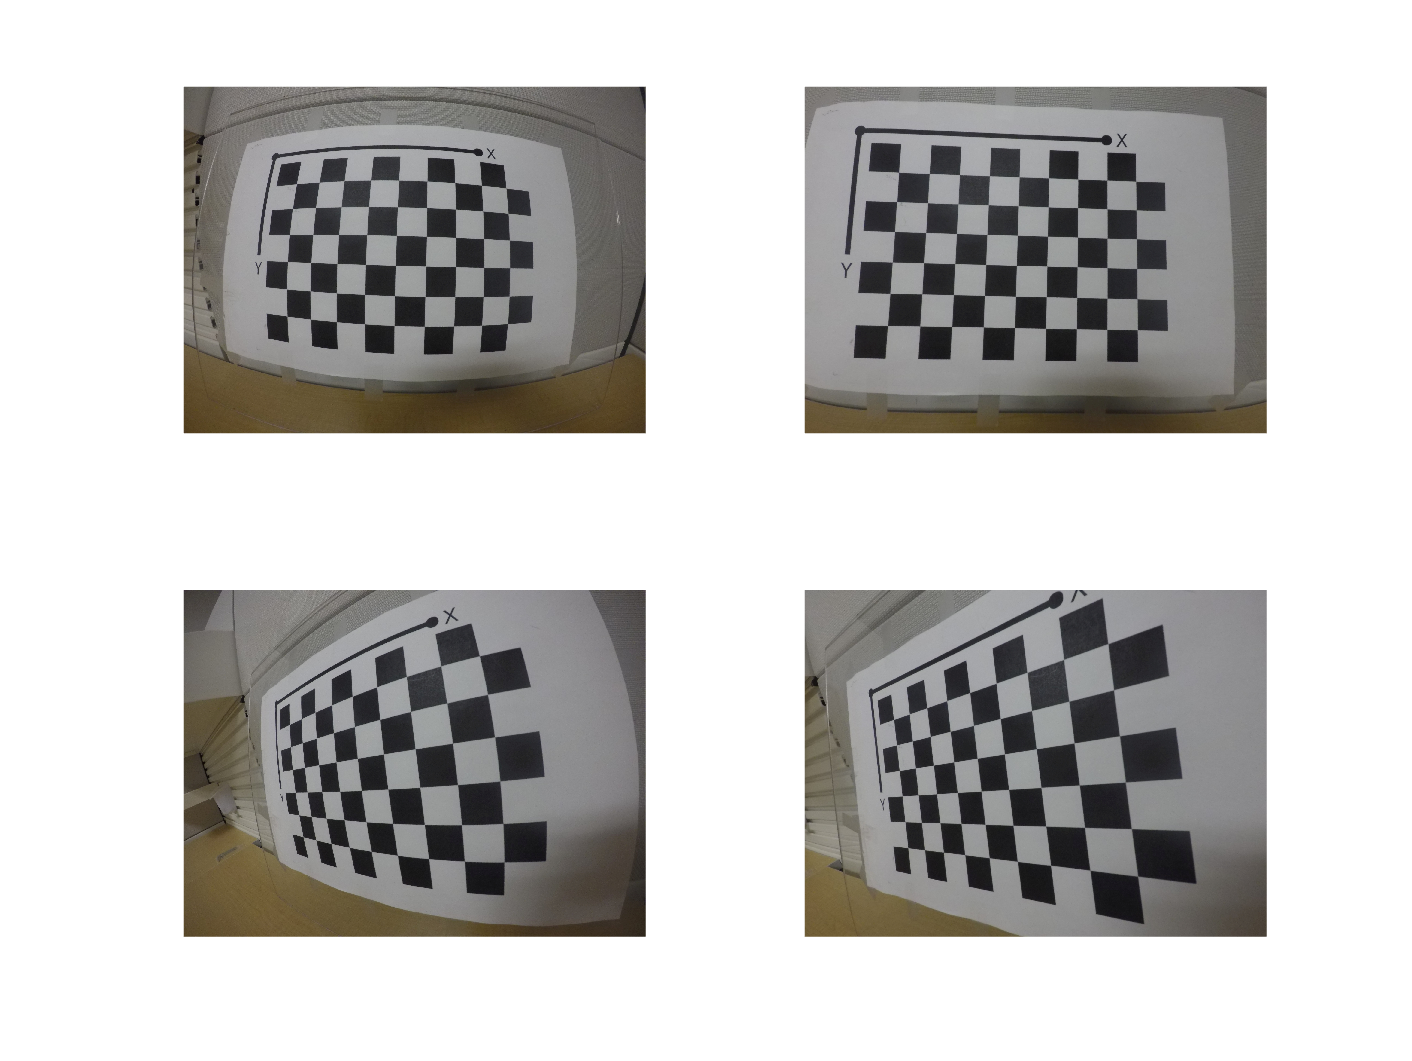

%EJERCICIO 15
%R3 = parametrosRealSense.RotationMatrices(:,:,3);
numImagen = 3;
R= parametrosRealSense.RotationMatrices(:,:,numImagen)

%t3 = parametrosRealSense.TranslationVectors(3,:);
t = parametrosRealSense.TranslationVectors(numImagen,:)

figure
%imRS20 = imread('.\RealSense\realsense20.png');
%imshow(imRS20); hold on
imshow(imread(sprintf("./Realsense/realsense%02d.png", 20)));
hold on; axis on; grid on;

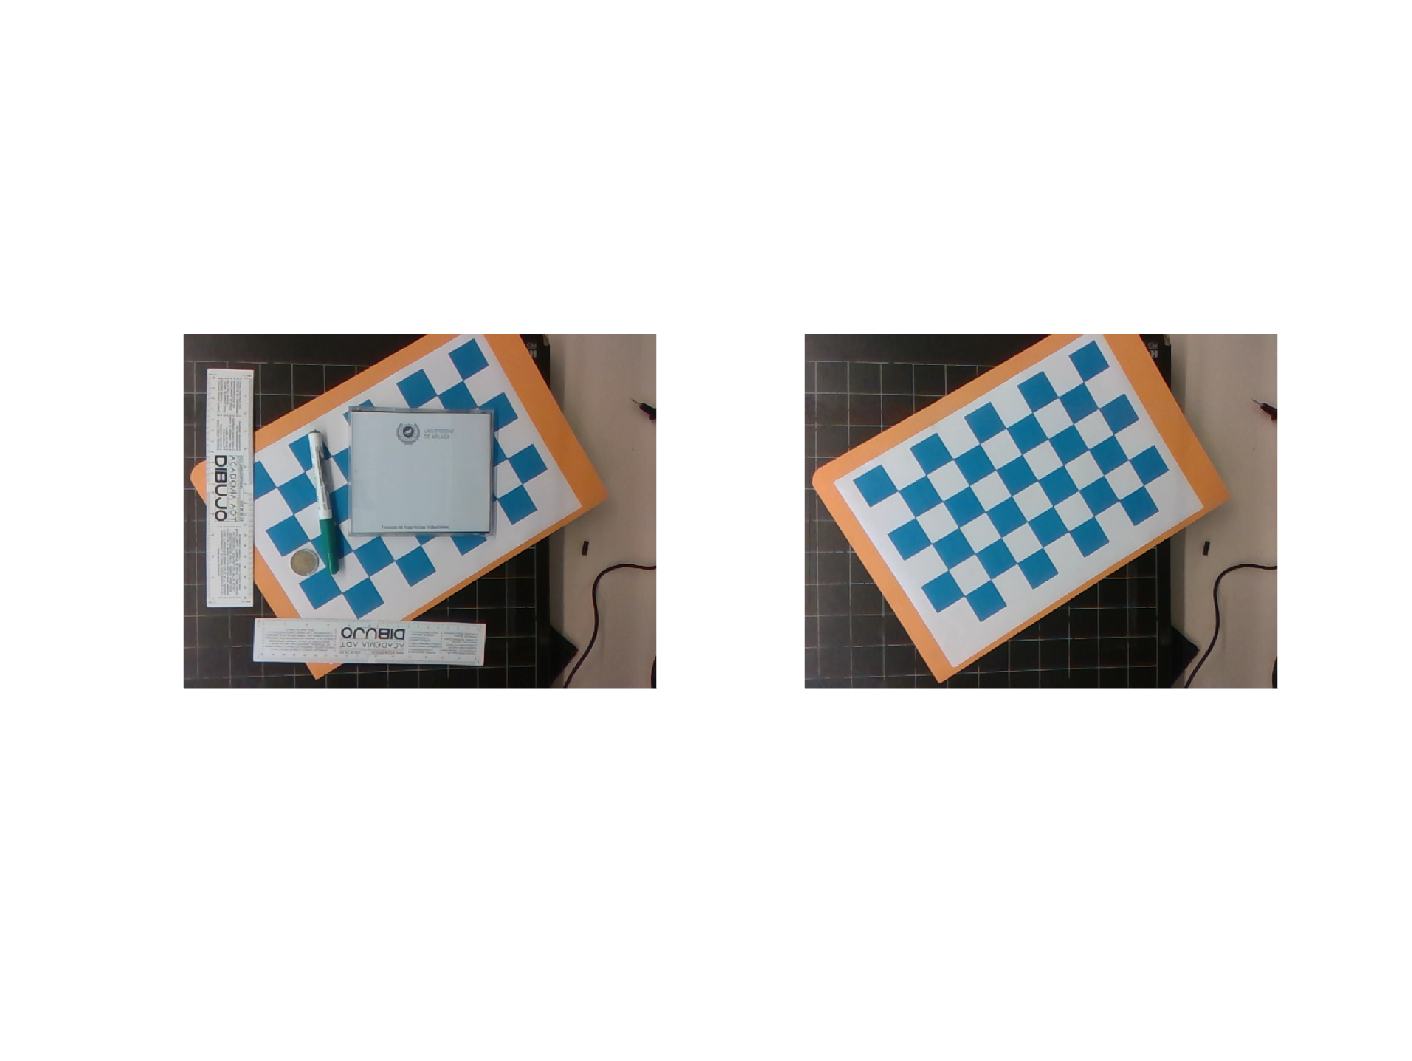


%puntosImagen = ginput(2);
puntos2d = ginput(2);

%plot(puntosImagen(:,1),puntosImagen(:,2),'g%);
plot(puntos2d(:, 1), puntos2d(:,2), 'y');

%% puntos3D = pointsToWorld(parametrosRealSense,R3,t3,puntosImagen);
%puntos3D = img2world2d(puntos2d,cal.PatternExtrinsics(3),cal.Intrinsics);
%!M =  [R ; t] * K % paso de coordenades del mundo real a pixeles de la cámara
puntos3d = pointsToWorld(parametrosRealSense, R, t, puntos2d);

%distan = (sqrt((puntos3D(1,1)-puntos3D(2,1))^2+(puntos3D(1,2)-puntos3D(2,2))^2))/10;
%% distan=norm(puntos3D(1,:)-puntos3D(2,:))/10

dist = norm(puntos3d(1,:)-puntos3d(2,:));

%text((puntosImagen(1,1)+puntosImagen(2,1))/2, ...
% (puntosImagen(1,2)+puntosImagen(2,2))/2, ...
% ['Distancia = ', num2str(distan),' cm.'],'Color','y%);
%!K = parametrosRealSense.IntrinsicMatrix % esta es la que usamos, cx=323.4 (640/2), cy=240.6 (480/2)

R =     0.8509   -0.5193    0.0794
    0.5152    0.8545    0.0662
   -0.1022   -0.0154    0.9946


etiqueta = sprintf("P1=(%0.0f,%0.0f)->(%0.0f,%0.0f)", puntos2d(1,1), puntos2d(1,2),puntos3d(1,1), puntos3d(1,2));
text (puntos2d(1,1),puntos2d(1,2),etiqueta,'Color','y');
etiqueta = sprintf("P2=(%0.0f,%0.0f)->(%0.0f,%0.0f)", puntos2d(2,1), puntos2d(2,2),puntos3d(2,1), puntos3d(2,2));

t =  -138.4257  -19.3017  427.2958


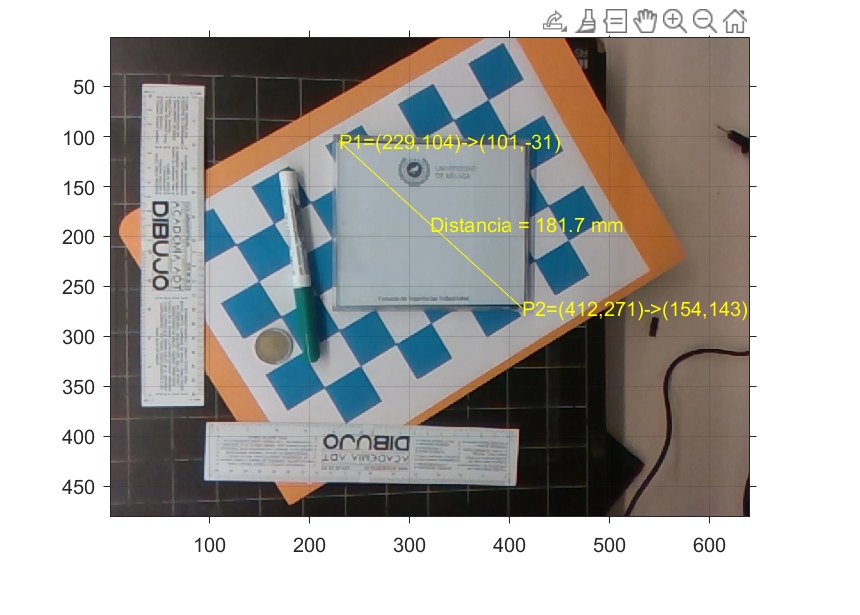

text (puntos2d(2,1),puntos2d(2,2),etiqueta,'Color','y');
etiqueta = sprintf("Distancia = %0.1f mm", dist);
text (mean(puntos2d(:,1)),mean(puntos2d(:,2)),etiqueta,'Color','y');

NOTA: La caratula trasera de un CD mide 14x12 cm, un rotulador 14 cm, una moneda de 2 euros 2.5 cm de diámetro y cada celda de la rejilla es de 3x3 cm.